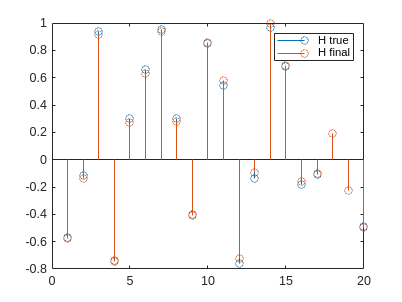

%this project takes in a reference noisy signal
%and a signal mixed with a similar noise and attempts
%to get the signal that has been mixed


projectData = load("noiseCancelData.mat");



%sets our filter length
filterLength = 20;

%sets our mu value for propogation
mu = 0.001;

%sets the initial arrays
h_initial = zeros([filterLength 1]);


%writes the eta and z to csv files
csvwrite("noise_cancel_eta.csv", projectData.eta)
csvwrite("noise_cancel_z.csv", projectData.z)

%calls the lms function to get the noise cancelled signal
[noise, signal, h_final] = lms(projectData.eta, projectData.z, mu, h_initial);


%stem plots the h_true filter
stem(projectData.h_true);
hold on;
stem(h_final);
legend("H true", "H final");
hold off;

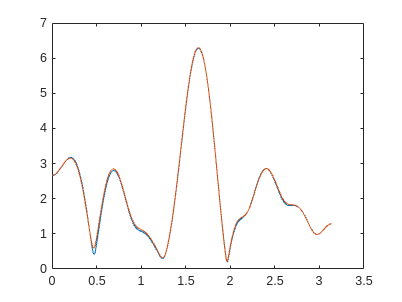





%plots the frequency response of the h_true and h_calculated
[h_0, w_0] = freqz(h_final, 1, 1000);
[h_1, w_1] = freqz(projectData.h_true, 1, 1000);

plot(w_0, abs(h_0));
hold on;
plot(w_1, abs(h_1));
hold off;

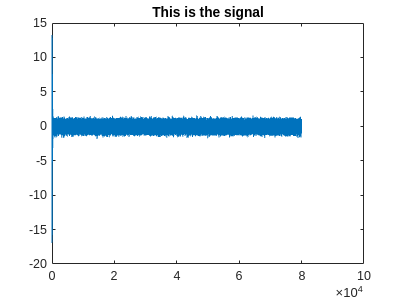




%plots the signal
plot(signal);
title("This is the signal");

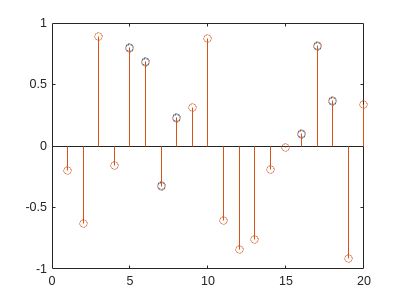




%creates the filtered signal player
filteredSignalPlayer = audioplayer(signal, projectData.fs);
%playblocking(filteredSignalPlayer);


%does the second signal filtering
[noise2, signal2, h2] = lms(projectData.eta2, projectData.z2, mu, h_initial);

secondfilteredSignalPlayer = audioplayer(signal2, projectData.fs);
playblocking(secondfilteredSignalPlayer);

%plots the second h
stem(h2)
hold on;
stem(projectData.h_true2);
hold off;